# Fantasia Database

## **f1o01**

Directly plot ECG signal from .dat file

According to 250Hz sampling rate, the fist 2500 samples show the first 10 seconds of signal

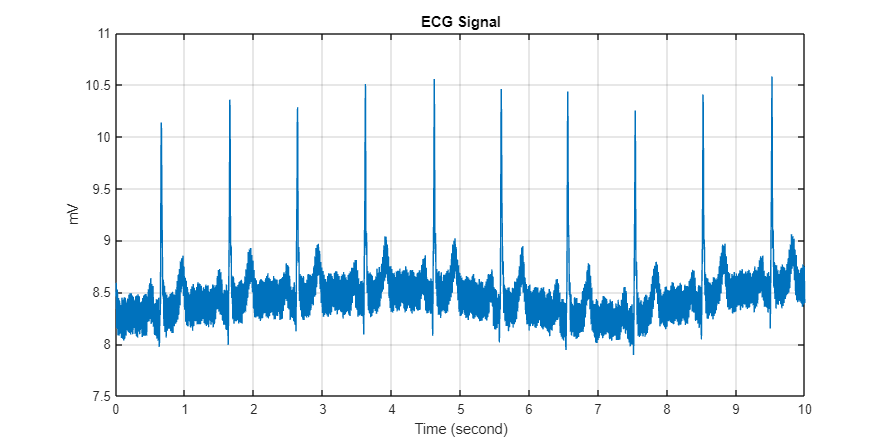

[sig, ~, tm] = rdsamp('Data/f1o-01/f1o01.dat', 2, 2500);
fig = figure(); 
fig.Position(3:4) = [3000, 1500];
plot(tm, sig);
title('ECG Signal');
xlabel('Time (second)');
ylabel('mV');
grid on;

Converint .dat file into .mat file for better compatiblity woth MATLAB

Then load data into MATLAB and ploting first 10 seconds of ECG signal

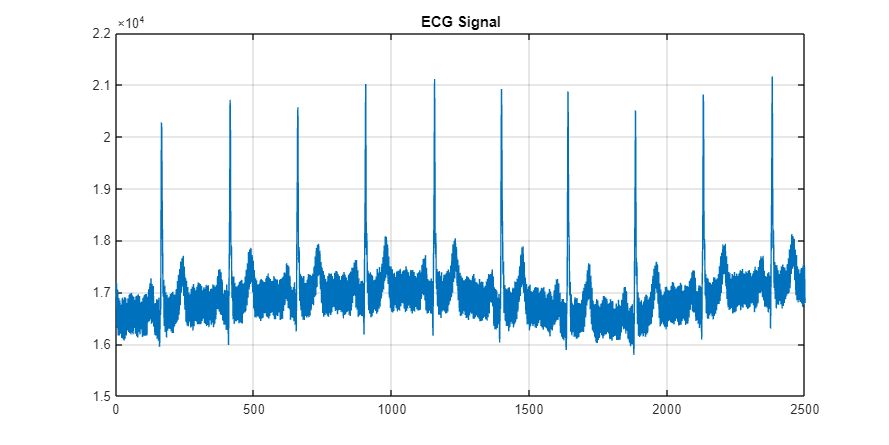

wfdb2mat('Data/f1o-01/f1o01');
data = load("f1o01m.mat");
fig = figure(); 
fig.Position(3:4) = [3000, 1500];
time = 1:2500;
plot(time, data.val(2,1:2500));
title('ECG Signal');
grid on;

# ECG-ID Database

## **person 1 - rec 14**

Directly plot ECG signal from .dat file

According to 500Hz sampling rate, the fist 5000 samples show the first 10 seconds of signal

[sig, ~, tm] = rdsamp('Data/person 1 - rec 14/rec_14.dat', 1, 5000);

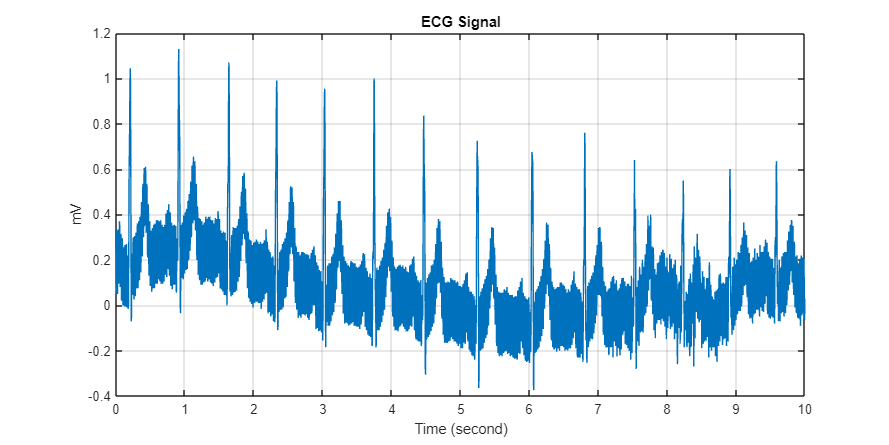

fig = figure(); 
fig.Position(3:4) = [3000, 1500];
plot(tm, sig);
title('ECG Signal');
xlabel('Time (second)');
ylabel('mV');
grid on;

[sig, ~, tm] = rdsamp('Data/person 1 - rec 14/rec_14.dat', 2, 5000);

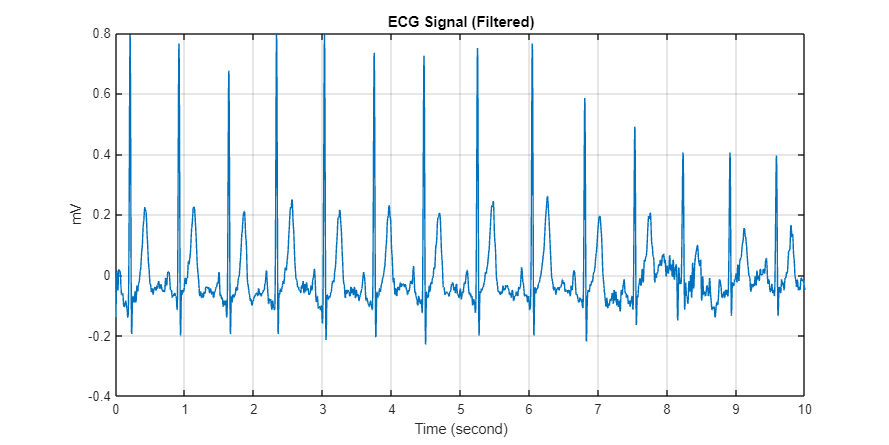

fig = figure(); 
fig.Position(3:4) = [3000, 1500];
plot(tm, sig);
title('ECG Signal (Filtered)');
xlabel('Time (second)');
ylabel('mV');
grid on;

Converint .dat file into .mat file for better compatiblity woth MATLAB

Then load data into MATLAB and ploting first 10 seconds of ECG signal

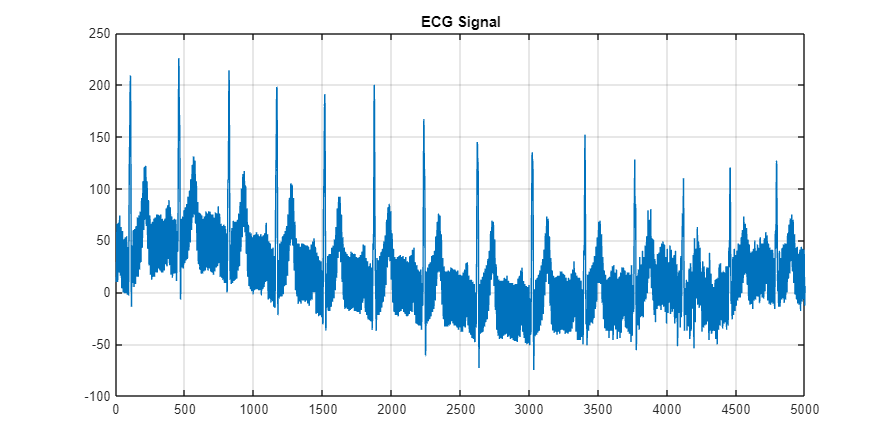

wfdb2mat('Data/person 1 - rec 14/rec_14');
data = load("rec_14m.mat");
fig = figure(); 
time = 1:5000;
fig.Position(3:4) = [3000, 1500];
plot(time, data.val(1,1:5000));
title('ECG Signal');
grid on;

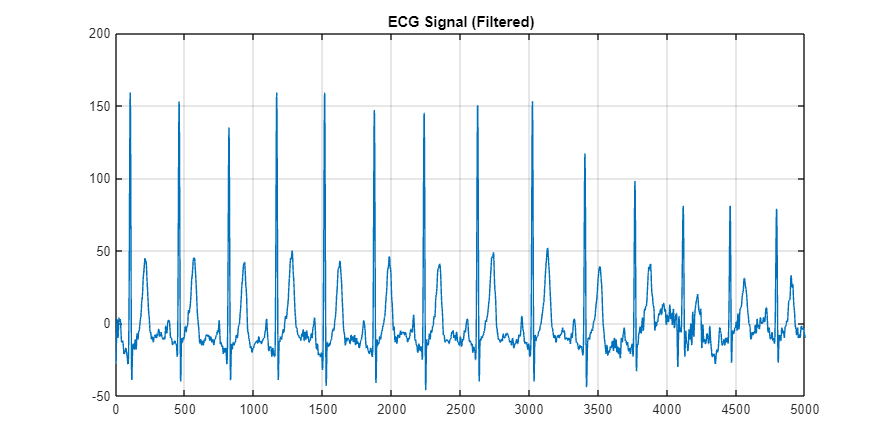

fig = figure(); 
fig.Position(3:4) = [3000, 1500];
plot(time, data.val(2,1:5000));
title('ECG Signal (Filtered)');
grid on;